# **Evaluación 1 | Procesamiento de señales e imágenes 2023-1**

*Estudiante: Nícolas Farfán Cheneaux*

*Profesor: Max Chacón*

*Ayudante: Luis Corral*

### Pregunta 1

Para calcular la frecuencia alias (fa) usando herramientas del dominio del tiempo, se seguirán los siguientes pasos:

1) Identificar los picos de la señal con findpeaks.

2) Calcular la distancia en tiempo entre los picos de la señal.

3) Se obtiene el periodo y a partir de este, se obtiene la frecuencia.

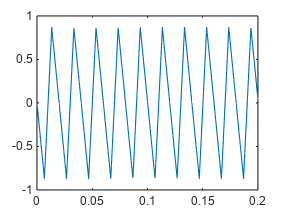

clearvars
% Se lee el archivo de audio de la señal
[x_n,Fs] = audioread('senal_1.wav');

% Visualizar la señal en el dominio del tiempo
d = length(x_n)/Fs;
t = linspace(0, d,length(x_n));
figure;
plot(t,x_n);
xlim([0 0.2]); % Se acota para visualizar de manera clara


% Calculo de la frecuencia alias usando herramientas del domino del tiempo (fa)

% Se indentifican los picos de la señal
[pks, locs] = findpeaks(x_n);

% Se calcula la distancia en el tiempo entre los picos de la señal
time_diff = diff(locs)/Fs;
periodo = mean(time_diff)

periodo = 0.0200


% Se obtiene la frecuencia de la señal
fa = 1/periodo;
disp(['La frecuencia alias de la señal es ', num2str(fa), ' Hz']);

La frecuencia alias de la señal es 50 Hz


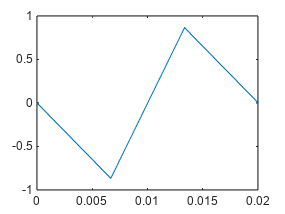


% Gráficamente podemos comprobar viendo un periodo de la señal
plot(t,x_n);
xlim([0 periodo]);


% Calculo de la frecuencia muestreada originalmente (f)
% f = |fa - Fs [fa / Fss]|
f = abs(fa - Fs*ceil(fa/Fs))

f = 100.0000

disp(f)

  100.0000



disp(['La frecuencia original es ', num2str(f), ' Hz']);

La frecuencia original es 100 Hz


### Pregunta 2

clearvars
[y_n,Fs2] = audioread('1kHz_44100Hz_16bit_05sec.wav');
y_n

y_n =          0
    0.0982
    0.1945
    0.2867
    0.3733
    0.4522
    0.5219
    0.5811
    0.6286
    0.6632


n = -5:5

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5


Fs2 % Frecuencia de muestreo

Fs2 = 44100

Fc = 800

Fc = 800

Fr = Fs2 / Fc

Fr = 55.1250

x_n = n == 0

x_n = 1×11 logical array
   0   0   0   0   0   1   0   0   0   0   0



% Filtro Butterworth
% Dado que H[z] = Y[z] / X[z]

a1 = ((2*(tan(pi/Fr)^2-1)) / (1 + (2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)))

a1 = -1.8391

a2 = ((1-2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2))

a2 = 0.8511


b2 = (tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)

b2 = 0.0030

b0 = b2

b0 = 0.0030

b1 = 2*b0

b1 = 0.0060



% Vector de sumandos "b": 0 1 2
b = [b0 b1 b2]

b =     0.0030    0.0060    0.0030



% Vector de sumandos "a": 1 2
a = [a1 a2]

a =    -1.8391    0.8511



% Obtención de la salida del sistema y[n]
y_n = filter(b, a, x_n)

y_n =          0         0         0         0         0   -0.0016   -0.0040   -0.0035   -0.0016   -0.0007   -0.0003



% Obtención de la respuesta al impulso h[n]
h_n = impz(b, a, n)

h_n =          0
         0
         0
         0
         0
   -0.0016
   -0.0040
   -0.0035
   -0.0016
   -0.0007


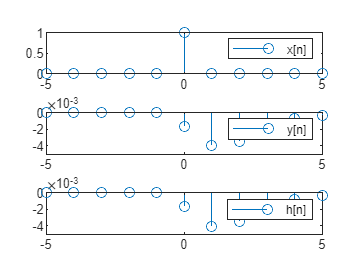


% Gráfico
subplot(3, 1, 1)
stem(n, x_n)
legend('x[n]')
subplot(3, 1, 2)
stem(n, y_n)
legend('y[n]')
subplot(3, 1, 3)
stem(n, h_n)
legend('h[n]')

### Pregunta 3

Se desarrolla la ecuación de diferencias y se obtiene lo siguiente

clearvars
alpha = 0.6

alpha = 0.6000


% Column vectors
z = 0 % Zeros

z = 0

p = alpha % Poles

p = 0.6000

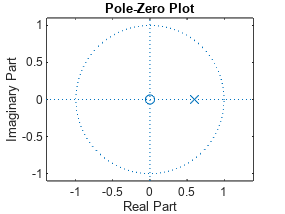

figure 
zplane(z, p)


% Row vectors
b = 1 % Numerador

b = 1

a = [1 -alpha] % Denominador

a =     1.0000   -0.6000


figure
zplane(b, a)

Como se puede apreciar en el diagrama se tiene los ceros:

z = 0

y  los polos

p = 0.6 (El valor de alpha)

Por lo que el sistema es estable dado que se encuentra dentro del círculo.